## Problem 5 (25 points)

Generate a dataset comprising a set of N real numbers drawn from the uniform distribution on [0, 1] . Consider various dataset sizes N = 5, 10, 20, 40, 60, 80, 100, 500, $10^3$ , $10^4$ . For each N , repeat the following experiment M := 100 times:

(i) first, generate the data,

(ii) then, compute the average $\hat \mu $ , and

(iii) finally, measure the error between the computed average $\hat \mu$ and the true mean µ as $|\hat \mu - \mu_{true}|$ .

### Part 1 [5 points]

For the uniform distribution, plot a single graph that shows the distribution of errors (across M repeats) for all values of N using a box-and-whisker plot. You may use the boxplot(.) function in Matlab.

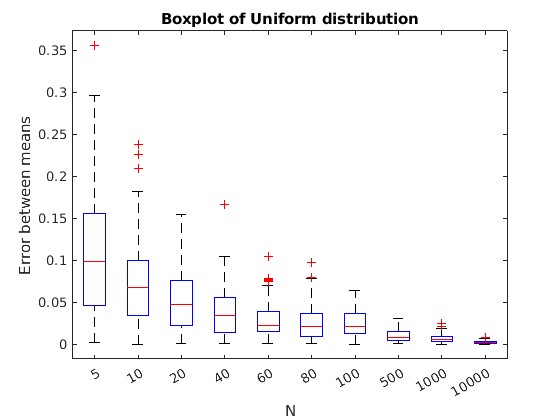

rng(1)
M = 100;
true_mean = 0.5; % true_mean of uniform distribution is 0.5
N = [5 10 20 40 60 80 100 500 10^3 10^4]; % An array of different values of N

error = [];
for i = 1:10 % loop over index of N
    % rand generate uniform random variables in [0,1]
    data = rand(M,N(i)); % M x N(i) Matrix of uniform random variables
    avg = sum(data,2)/N(i); % avg is a column vector containing the sum of each row.
    error = [error abs(avg-true_mean)]; % error is a M x N matrix with each column containing error for each value of N
end
boxplot(error); % boxplot of errors
title('Boxplot of Uniform distribution')
ylabel('Error between means')
xlabel('N')
xticklabels(N)

### Part 2 [5 points]

Repeat the above question by replacing the uniform distribution by a Gaussian distribution with µ := 0 and $\sigma^2$ := 1 .

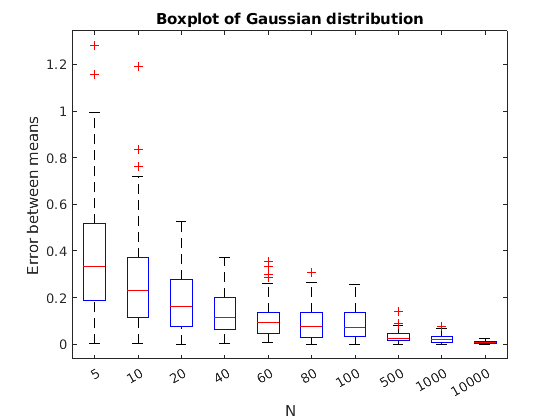

rng(1)
M = 100;
true_mean = 0; % true_mean of unit gaussian distribution is 0
N = [5 10 20 40 60 80 100 500 10^3 10^4]; % An array of different values of N

error = []; % loop over index of N
for i = 1:10
    % randn generate gaussian random variable with mean 0 and variance 1
    data = randn(M,N(i));  % M x N(i) Matrix of uniform random variables
    avg = sum(data,2)/N(i);  % taking sum column wise
    error = [error abs(avg-true_mean)];  % error is a M x N matrix with each column containing error for each value of N
end
boxplot(error); % boxplot of errors
title('Boxplot of Gaussian distribution');
ylabel('Error between means')
xlabel('N')
xticklabels(N)